# Trim, Linearise and design an **OBSERVER** for the quadcopter and **PENDULUM** model:

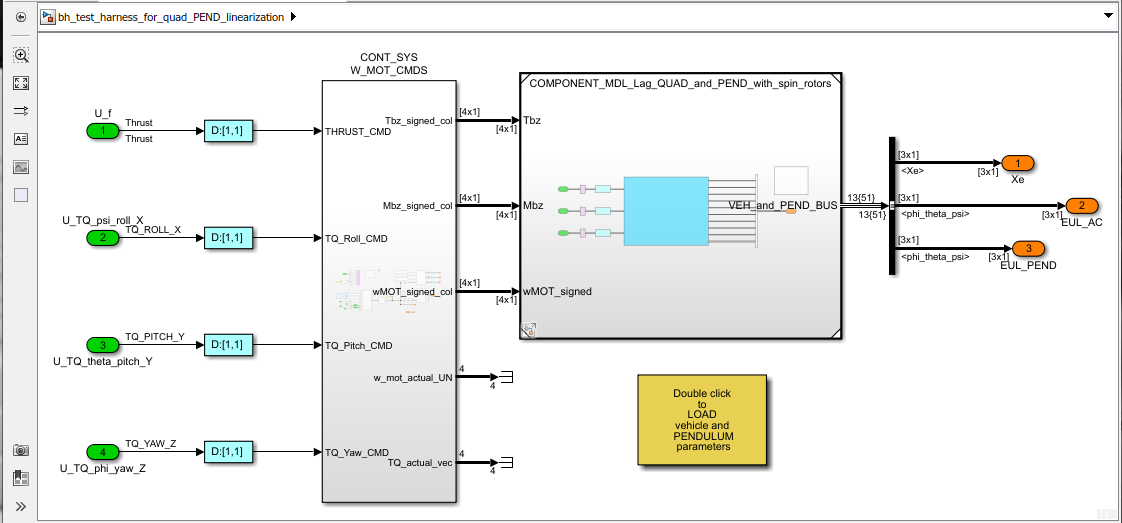

In this task we're going to linearise our **Simulink** quadcopter model. We're going to do this because we'd like to apply some "state space" control design techniques in order to design a control system for the quadcopter.  And as you know, these control techniques require a LINEAR plant model.  The workflow that we'll follow is this:

- We'll find an operating point for the pendulum. An operating point is characterized by the state(X), the input(U) and the output(Y).    We'll look specifically for an operating point that corresponds to steady state, ie: where the pendulum's state derivatives are ZERO. This is referred to as finding a **TRIMMED operating point**.

- We'll then use this TRIMMED operating point to calculate a **linearised** version of the quadcopter model.

- Finally, we'll then use this linearised model to design a full state feedback control system using the Linear Quadratic Integrator (LQI) technique.

`Bradley Horton : 08-Oct-2017, bradley.horton@mathworks.com.au`

# 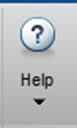 Take a moment !

If you're interested in reading about how to linearize a NON linear plant model.  Use the MATLAB HELP browser and try this simple text search

- `linearize control system`

HINT:  today we'll be using the functions:

- `operspec,   findop,   linearize`

## Load the model parameters:

bh_quad_params
bh_pend_params
bh_create_veh_and_pend_BUS

Just ensure that the the initial local Euler angles of the pendulum are ZERO:

P_pend.eul_loc_vec      = [0,0,0]'; % rad
P_veh_no_props.eul_init = [0,0,0]'; % rad

ANd echo the parameters that have been loaded into the workspace:

whos

  Name                   Size            Bytes  Class           Attributes

  PEND_BUS               1x1               310  Simulink.Bus              
  P_elec                 1x1               352  struct                    
  P_mot                  1x1              1232  struct                    
  P_mot_alone            1x1              1232  struct                    
  P_mot_vec              4x1              3584  struct                    
  P_one_prop             1x1               880  struct                    
  P_pend                 1x1               992  struct                    
  P_rot                  1x1               592  struct                    
  P_veh                  1x1              1536  struct                    
  P_veh_no_props         1x1              1536  struct                    
  VEH_AND_PEND_BUS       1x1               702  Simulink.Bus              
  XYZ_circ_mat          88x3              2112  double                    
  X_TS_OBJ              

warning('off')

## The name of the SIMULINK model that we'll linearise:

model  = 'bh_test_harness_for_quad_PEND_linearization_ALL_MEAS';
set_param(0, 'CallbackTracing', 'off')
open_system(model)

## Create the operating point specification object.

opspec = operspec(model);

In our operating point specification, note the following:

- Our GREEN root level INPORT blocks are the system inputs 

- Our ORANGE root level OUTPORT blocks are the system outputs 

display(opspec)


 Operating point specification for the Model bh_test_harness_for_quad_PEND_linearization_ALL_MEAS.
 (Time-Varying Components Evaluated at time t=0)

States: 
----------
(1.) DOT_phi
	 spec:  dx = 0,  initial guess: 0
(2.) DOT_theta
	 spec:  dx = 0,  initial guess: 0
(3.) DOT_psi
	 spec:  dx = 0,  initial guess: 0
(4.) 

For each of our model states we can specify "desired" values for each of the following.  

- `x           :`   initial guess for state value

- `SteadyState :`   a logical indicating we are looking for a dx=0 final value

- `Min         :`   minimum bound for state value

- `Max         :`   maximum bound for state value

For our problem, we're going to look for an operating point where ALL of our states are at SteadyState (ie: dx/dt=0)

%[ opspec.States(1).SteadyState]
%[ arrayfun(@(a) (a.SteadyState), opspec.States) ].'

Our trimming function(coming up next) will then look for an operating point that satisfies this specification:

## Look for the steady state operating point.

opt           = findopOptions('DisplayReport','off');
[op,opreport] = findop(model,opspec, opt);

Review our trimmed OPERATING point and NOTE the following:

- We have indeed found a steady state operating point because the state derivatives are either zero OR very small $O(10^{-7})$

- In this trimmed pose, ALL of the system outputs are ZERO.

- To maintain this trimmed pose we need to supply an INPUT force ... which is the force to counter gravity. 

display(opreport)


 Operating point search report for the Model bh_test_harness_for_quad_PEND_linearization_ALL_MEAS.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
(1.) DOT_phi
      x:             0      dx:     -7.85e-29 (0)
(2.) DOT_theta
      x:             0      dx:      9.58e-13 (0)
(3.) DOT_psi
  

## Linearize the model about this operating point:

Next we'll linearise our model about this trimmed operating point:

my_LIN_PLANT = linearize(model,op);

What are the size attributes of the linearized model ?

size(my_LIN_PLANT)

State-space model with 18 outputs, 4 inputs, and 18 states.


Note the names of the **INPUTS** "U"  

my_LIN_PLANT.InputName

ans = 4×1 cell array
    {'U_f'               }
    {'U_TQ_psi_roll_X'   }
    {'U_TQ_theta_pitch_Y'}
    {'U_TQ_phi_yaw_Z'    }


and the **OUTPUTS** "Y" 

my_LIN_PLANT.OutputName(1:3) = {'Xe','Ye','Ze'};
my_LIN_PLANT.OutputName

ans = 18×1 cell array
    {'Xe'                                                          }
    {'Ye'                                                          }
    {'Ze'                                                          }
    {'EUL_AC(1,1)'                                                 }
    {'EUL_AC(2,1)'                                                 }
    {'EUL_AC(3,1)'                                                 }
    {'EUL_PEND(1,1)'                                               }
    {'EUL_PEND(2,1)'                                               }
    {'EUL_PEND(3,1)'                                               }
    {'bh_test_harness_for_quad_PEND_linearization_ALL_MEAS/Ve(1,1)'}
    {'bh_test_harness_for_quad_PEND_linearization_ALL_MEAS/Ve(2,1)'}
    {'bh_test_harness_for_quad_PEND_linearization_ALL_MEAS/Ve(3,1)'}
    {'V_EUL_C(1,1)'                                                }
    {'V_EUL_C(2,1)'                                                }
    {'V_EUL_

and the **STATES** "X"

my_LIN_PLANT.StateName

ans = 18×1 cell array
    {'DOT_phi'       }
    {'DOT_theta'     }
    {'DOT_psi'       }
    {'DOT_Xe'        }
    {'DOT_Ye'        }
    {'DOT_Ze'        }
    {'DOT_phi_pend'  }
    {'DOT_theta_pend'}
    {'DOT_psi_pend'  }
    {'phi'           }
    {'theta'         }
    {'psi'           }
    {'Xe'            }
    {'Ye'            }
    {'Ze'            }
    {'phi_pend'      }
    {'theta_pend'    }
    {'psi_pend'      }


Check if the linearised system is Full state Feedback(FSFB) Controllable. If the system is NOT FSFB controllable it means that we can NOT ***arbitrarily position*** the system poles.  We may still be able to position them to obtain a stable system  ... it's just that we can't arbitrarily position them.

co = ctrb(my_LIN_PLANT);
% if(rank(co) ~= size(A,1) )
%     error('###_ERROR: the system is NOT FSFB controllable');
% end

And close the model:

close_system(model)
set_param(0, 'CallbackTracing', 'on')

## OK, reduce the system

my_plant = minreal(my_LIN_PLANT);

2 states removed.


size(my_plant)

State-space model with 18 outputs, 4 inputs, and 16 states.


my_plant.C

ans =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0004   -0.9392    0.3433    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.3433   -0.9392    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -1.0000
    0.0000   -0.0000   -0.0000    0.5000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.3653    0.3414    0.0004    0.0000   -0.0000    0.0000
    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    1.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.0000    0.0000   -0.0000    0.7071    0.0000    0.0009   -0.0001    0.0000   -0.0000    0.0000    0.5166   -0.4828   -0.0006   -0.0000    0.0000    0.0000
    0.0000    0.0000   -0.00

## OK, design an observer for the REDUCED plant

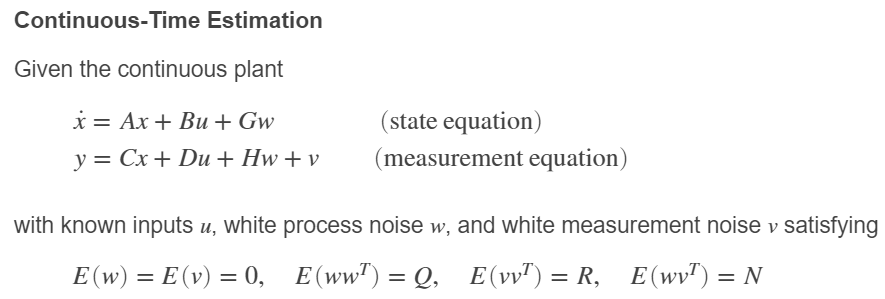

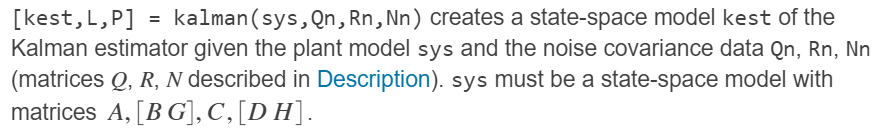


new_input_names = [         string(my_plant.InputName); ...
                 ("w_" + string(my_plant.InputName))  ];
             
new_input_names = cellstr(new_input_names);  
        
the_sys = ss(my_plant.A, [my_plant.B, my_plant.B], ...
                      my_plant.C, ...
                     [my_plant.D,my_plant.D], 'inputname', new_input_names);

[Nx,Ny,Nu] = deal(size(my_plant.A,1), size(my_plant.C,1), size(my_plant.B,2));

Qobs = 1    * diag(ones(1,Nu));
Robs = 1e-4 * diag(ones(1,Ny));

%[the_sys, Qn, Rn] = LOC_plant_for_KAL_design(my_plant);
[kest,~,~] = kalman(the_sys,Qobs,Robs,[]);

size(kest)

State-space model with 34 outputs, 22 inputs, and 16 states.


# OK, design a CONTROLLER for the REDUCED plant

## Control design:

We'll use the approach described by the LQI() function, ie::

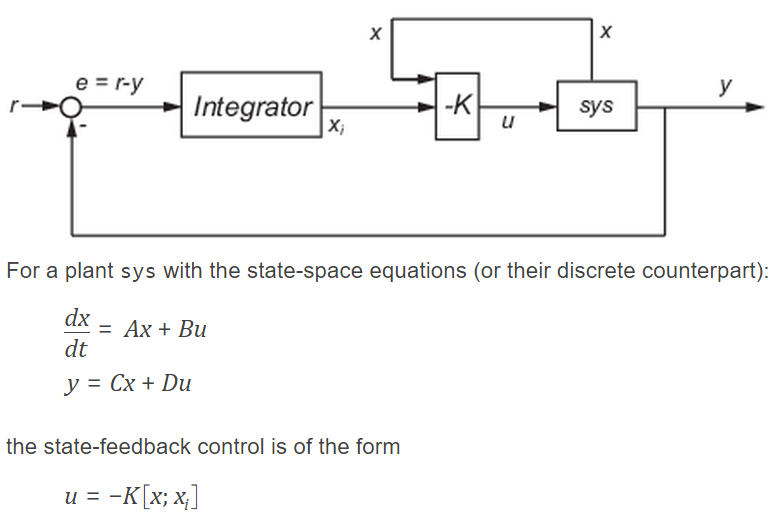

Note that:  

- 
$$K\in R^{N_u \times \left(N_x +N_y \right)}$$


size(my_plant)

State-space model with 18 outputs, 4 inputs, and 16 states.



my_plant_for_CLD   = my_plant(1:3,:); % only keep the first 3 outputs

Nx_CLD = size(my_plant_for_CLD.A,1);  
Nu_CLD = size(my_plant_for_CLD.B,2);  
Ny_CLD = size(my_plant_for_CLD.C,1);

Now design a full state feedback controller using `LQI()`. NOTE the following:

- you will need to experiment with the Q,R weighting matrices

P_pend.eul_loc_vec = [0;1;1]/20

P_pend = struct with fields:
           mass: 0.2500
          L_xyz: [3×1 double]
          T_xyz: [3×1 double]
              I: [3×3 double]
    eul_loc_vec: [3×1 double]


tmp        = 1*[ones(1, Nx_CLD+Ny_CLD)];
tmp((end-2):end) = [2,2,1500];
Q          = 1*diag(tmp); 
%tmp        = 5e2*[1,1,1,1]; 
%tmp        = 5e5*[1,0.1,0.1,0.1]; 
tmp        = 1e5*[1, 0.1,0.1,0.0001];
R          = diag(tmp);
%-------------------------------


[K_red,~,~] = lqi(my_plant_for_CLD,Q,R,[])

K_red =    -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0007   -0.0006    1.1074   -0.0004    0.0001   -0.5208   -0.0000   -0.0000   -0.1225
   -0.1414   -1.5806    0.2556   -0.2197    0.0000    0.0059   -0.0018   -0.0000    0.0000   -0.0452   -0.1599    0.1507    0.0002   -0.0127   -0.0349    0.0000   -0.0000   -0.0141    0.0000
   -0.0002    0.0064   -0.0010   -0.0010    0.0005    1.5229   -0.4946   -0.1414   -0.3107    0.0009    0.0301    0.0337    0.0000    0.0349   -0.0127   -0.0000    0.0141    0.0000   -0.0000
    0.0000    0.0000   -0.0000    0.2236   -0.3258    0.0001   -0.0000    0.0000   -0.0000   -0.0000   -0.1634    0.1527    0.0002    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000


What does the gain matrix K, look like?

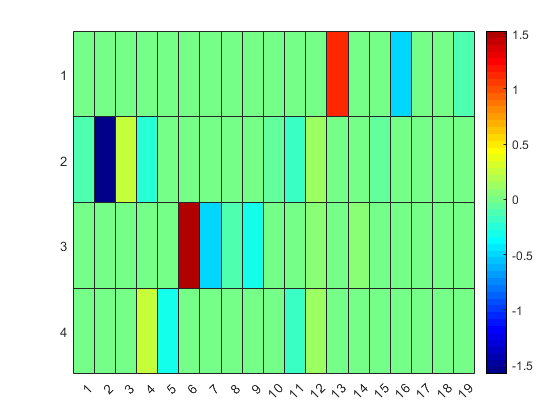

hfig = figure;
   heatmap(K_red,'Colormap', jet(50) );

What do the closed loop poles look like ?

A_hat = [  my_plant_for_CLD.A,   zeros(Nx_CLD,Ny_CLD);
          -my_plant_for_CLD.C,   zeros(Ny_CLD,Ny_CLD) ];
      
B_hat = [ my_plant_for_CLD.B;
          zeros(Ny_CLD,Nu_CLD) ];
p_lqi = esort( pole( ss((A_hat-B_hat*K_red),[],[],[]) ) )

p_lqi =   -0.2352 + 0.4073i
  -0.2352 - 0.4073i
  -0.4703 + 0.0000i
  -0.9779 + 0.6715i
  -0.9779 - 0.6715i
  -0.9779 + 0.6715i
  -0.9779 - 0.6715i
  -1.0005 + 0.0000i
  -1.0990 + 1.8588i
  -1.0990 - 1.8588i


Load params for models:

bh_create_local_params_QP_and_CONTROL_LAW


--------------------------------------------------
 ATTENTION:  (from bh_create_local_params_QP_and_CONTROL_LAW)

     Have just loaded Control Law into Workspace
--------------------------------------------------
###
##
#



# Local Subfunctions ONLY beyond this point

Generic:

- 
$$\begin{array}{l}
\dot{x} =A\ldotp x\;\;\;+\;\;\;B\ldotp u\;\;\;+\;\;G\ldotp w\\
y=C\ldotp x\;\;\;+\;\;D\ldotp u\;\;\;+\;\;H\ldotp w\;\;+\;\;v
\end{array}$$


My case:

- 
$$\begin{array}{l}
\dot{x} =A\ldotp x\;\;+\;\;B\ldotp \left(u\;+\;w\right)\\
y=C\ldotp x\;\;+\;D\ldotp \left(u+w\right)+\;\;v
\end{array}$$


%  function [the_sys, Qn, Rn] = LOC_plant_for_KAL_design(my_plant)
%      
%      new_input_names = [         string(my_plant.InputName); ...
%                          ("w_" + string(my_plant.InputName))  ];
%      new_input_names = cellstr(new_input_names);                
%     %  new_output_names = [         string(my_plant.OutputName), ...
%     %                      ("w_" + string(my_plant.OutputName))  ];                 
%     
%     the_sys = ss(my_plant.A, [my_plant.B, my_plant.B], ...
%                               my_plant.C, ...
%                              [my_plant.D,my_plant.D], 'inputname', new_input_names);
%     
%     [Nx,Ny,Nu] = deal(size(my_plant.A,1), size(my_plant.C,1), size(my_plant.B,2));
%     
%      Qn = 1*diag(ones(1,Nu));
%      Rn = 1*diag(ones(1,Ny));
%   
%  end